## Walkthrough with paired single cell RNA-seq and ATAC-seq data of Kidney cells

### Load data

addpath('./Data')
load('Kidney_sciCAR_data.mat');

### Process data and select features

This step includes two aspects: Removing cells and features in low quality and selecting features.

#### Process scRNA-seq data

minCells = 10; minCounts = 500; 
proData1 = preprocessing(RNA,minCells,minCounts);

processing data:


X1_all = proData1.data; Genes_all = proData1.Features; Cells1 = proData1.Cells;

#### Gene selection: if there are experiment conditions (e.g. time series), we select differentially expressed genes by Wilcoxon rank test, we select high variable genes otherwise.

condition = []; system_used = 'Mac';
r = []; fc = []; cutoff = []; flag = 2;
id1 = gene_selection(X1_all,condition,system_used,r,fc,cutoff,flag);

selecting genes:
Loading required package: ggplot2
Loading required package: hydroGOF
Loading required package: zoo

Attaching package: ‘zoo’

The following objects are masked from ‘package:base’:

    as.Date, as.Date.numeric

Loading required package: glmnet
Loading required package: Matrix
Loading required package: foreach
Loaded glmnet 2.0-18

Loading required package: StatMatch
Loading required package: proxy

Attaching package: ‘proxy’

The following object is masked from ‘package:Matrix’:

    as.matrix

The following objects are masked from ‘package:stats’:

    as.dist, dist

The following object is masked from ‘package:base’:

    as.matrix

Loading required package: clue
Loading required package: survey
Loading required package: grid
Loading required package: survival

Attaching package: ‘survey’

The following object is masked from ‘package:graphics’:

    dotchart

Loading required package: RANN
Loading required package: lpSolve
Loading required package: fpc
Loading requir

X1 = X1_all(id1,:); Genes = Genes_all(id1);

#### Process scATAC-seq data

minCells = 5; minCounts = 200;
proData2 = preprocessing(ATAC,minCells,minCounts);

processing data:


X2 = proData2.data; Loci = proData2.Features; Cells2 = proData2.Cells;

#### Loci selection (optional): To reduce the dimension of chromatin accessibility profiles, we just focus on near loci of high variable genes. Note: we did not do this step in the paper. If you want to shorten running time, you can uncomment the following steps.

species = 'mouse';
system_used = 'Mac';
genes_regions = search_gene_loci(Genes,system_used,species);


Batch submitting query [=====>-------------------------]  20% eta:  1m
Batch submitting query [========>----------------------]  30% eta:  1m
Batch submitting query [===========>-------------------]  40% eta:  1m
Batch submitting query [===============>---------------]  50% eta:  1m
Batch submitting query [==================>------------]  60% eta:  1m
Batch submitting query [=====================>---------]  70% eta: 42s
Batch submitting query [========================>------]  80% eta: 30s
Batch submitting query [===========================>---]  90% eta: 16s
Batch submitting query [===============================] 100% eta:  0s
                                                                      


bin = 50000;
genes_nearby_loci = search_nearby_loci(Genes,Loci,Loci,system_used,bin,species);
[~,~,id2] = intersect(genes_nearby_loci,Loci,'stable');
X2 = X2(id2,:);
Loci = Loci(id2);

#### Intersect scRNA-seq and scATAC-seq

[~,index1,index2] = intersect(Cells1,Cells2,'stable');
Cells = Cells1(index1); X1_all = X1_all(:,index1);
prior_clusters = prior_clusters(index1);
X1 = X1(:,index1); X2 = X2(:,index2);
c1 = median(X1(X1 ~= 0)); c2 = median(X2(X2 ~= 0));
X2 = X2/c2*c1;
RNA = array2table(X1,'RowNames',Genes,'VariableNames',Cells);
ATAC = array2table(X2,'RowNames',Loci,'VariableNames',Cells);
RNA_all = array2table(X1_all(:,index1),'RowNames',Genes_all,'VariableNames',...
    Cells);

### Run scAI

K = 20; alpha = 1; lambda = 100000; gamma = 1; s = 0.25; Inits = []; repeat = 1;
result = run_scAI(X1,X2,K,alpha,lambda,gamma,s,Inits,repeat);
best_one = result{repeat};

### Downstream analyses

After decomposing transcriptomic and epigenomic data into multiple biologically relevant factors (i.e., gene, locus and cell loading matrices), scAI enables a variety of downstream analyses, including the following four steps:

- Identify cell clusters

- Umap visualization

- Identify factor / cluster specific markers

- Visualize markers alongside the cells in two-dimensions using VscAI

#### 1 Identify cell clusters 

numCluster = [];
plot_or_not = 0;
term = [];
colors = [];
cluster_form = 'Leiden';
system_used = 'Mac';
clust = cell_cluster(best_one,Cells,numCluster,plot_or_not,term,colors,...
    cluster_form,system_used);

Warning message:
package ‘reticulate’ was built under R version 3.5.2 


#### 2 Umap visualization

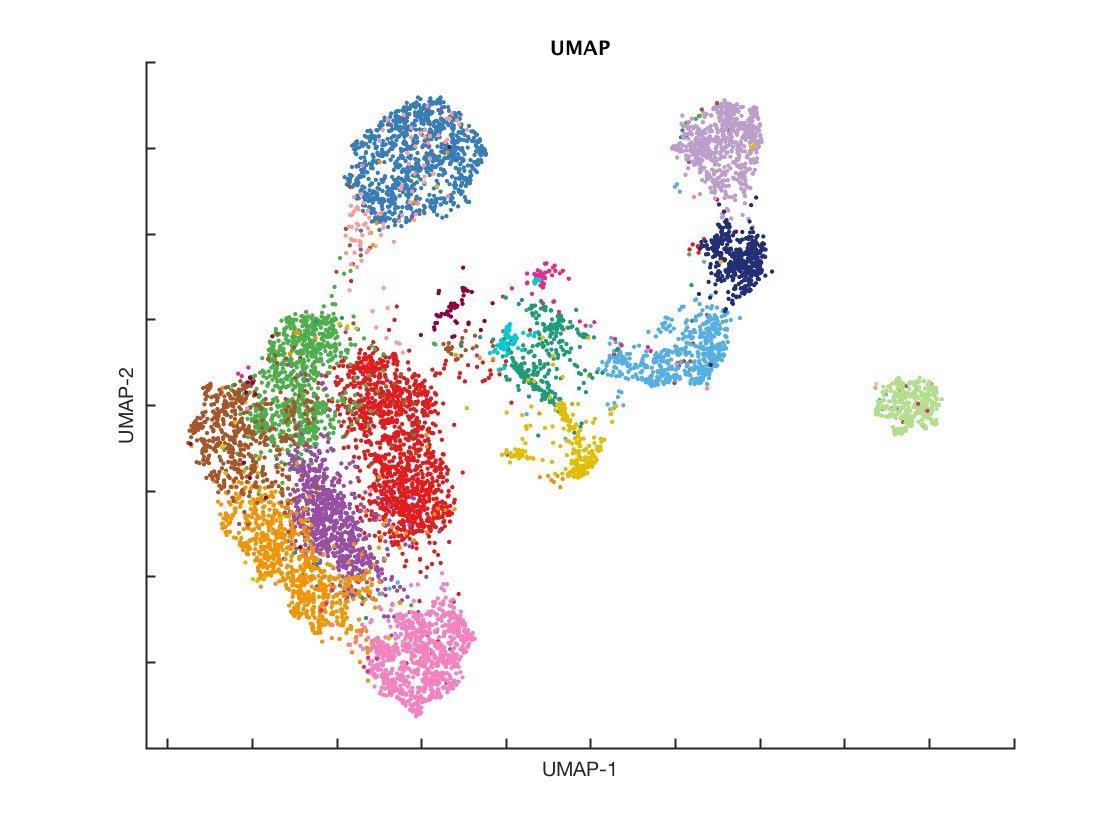

H = best_one.H;
method = 'UMAP';
cell_coords = reducedDims(H,Cells,method);
title_name = 'UMAP';
cellVisualizaiton(cell_coords,clust,term,colors,title_name,method);

Feature plot

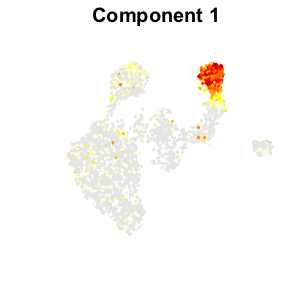

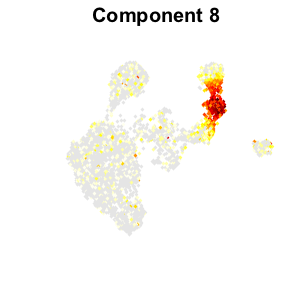

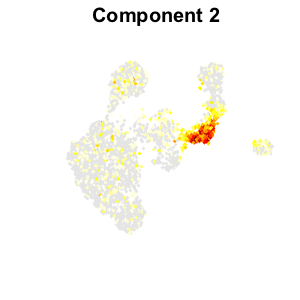

index = [1,8,2];
Feature_plot(H,cell_coords,index)

#### 3a Identify component specific markers

W1 = best_one.W1; W2 = best_one.W2; 

Identify factor specific genes

[factor_genes, factor_topgenes] = identifyFactorMarkers(X1,W1,H,Genes);

Identify factor specific loci

[factor_loci, factor_toploci] = identifyFactorMarkers(X2,W2,H,Loci);

Plot the rank of marker genes, which are given by the user or use top genes of each factor (topngenes).

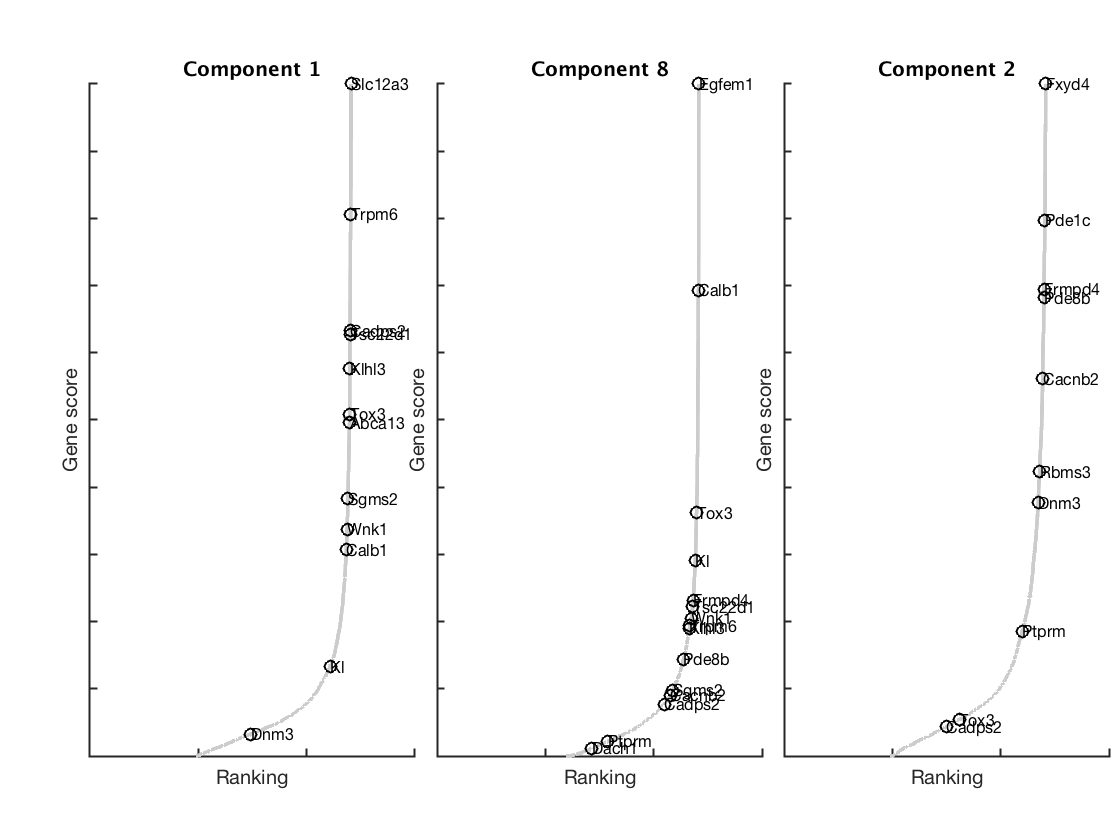

marker_genes = {'Slc12a3','Trpm6','Abca13','Klhl3','Wnk1','Tsc22d1','Cadps2',...
    'Egfem1','Calb1','Kl','Temem72','Dach1','Ptprm','Sgms2','Tox3','Frmpd4',...
    'Rbms3','Fxyd4','Dnm3','Cacnb2','Pde1c','Pde8b'};
top_per = 0.5;
featureRankingPlot(W1,Genes,marker_genes,[],index,top_per);

#### 3b Identify cluster specific markers

Identify cluster specific marker genes

[Top10genes,~,scale_RNA] = identify_cluster_specific_markers(RNA_all,system_used);


Attaching package: ‘dplyr’

The following objects are masked from ‘package:stats’:

    filter, lag

The following objects are masked from ‘package:base’:

    intersect, setdiff, setequal, union

Warning message:
package ‘dplyr’ was built under R version 3.5.2 
Warning message:
package ‘ggplot2’ was built under R version 3.5.2 
Warning message:
Feature names cannot have underscores '_', replacing with dashes '-'TRUE 
Centering and scaling data matrix

  |                                                                            
  |                                                                      |   0%
  |                                                                            
  |====                                                                  |   6%
  |                                                                            
  |========                                                 

plot the heatmap of cluster specific marker genes

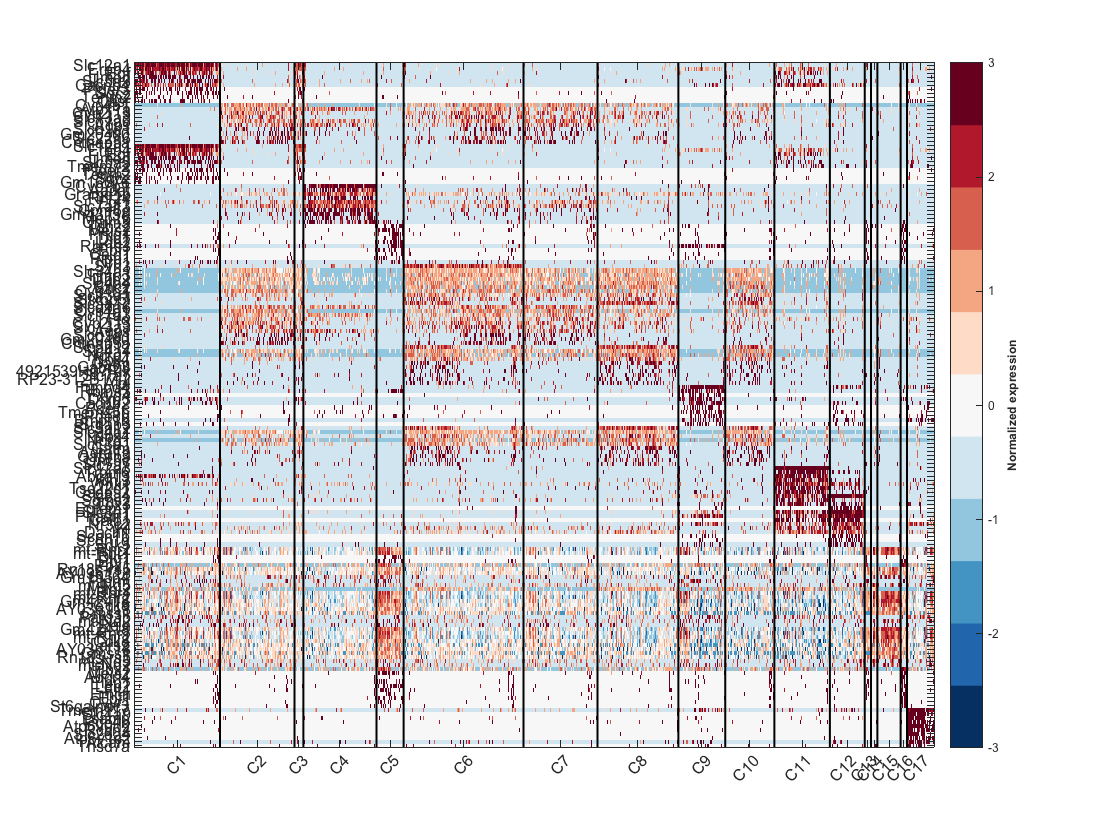

warning ('off','all');
plot_heatmap_markers(scale_RNA,clust,Top10genes);

Generate adjusted aggregated scATAC-seq data

X2a = generate_aggregated_matrix(X2,best_one,clust);
ATACa = array2table(X2a,'RowNames',Loci,'VariableNames',Cells);

Identify cluster specific marker loci

[Top10loci,marker_loci,scale_ATACa] = identify_cluster_specific_markers(ATACa,system_used);


Attaching package: ‘dplyr’

The following objects are masked from ‘package:stats’:

    filter, lag

The following objects are masked from ‘package:base’:

    intersect, setdiff, setequal, union

Warning message:
package ‘dplyr’ was built under R version 3.5.2 
Warning message:
package ‘ggplot2’ was built under R version 3.5.2 
Centering and scaling data matrix

  |                                                                            
  |                                                                      |   0%
  |                                                                            
  |=                                                                     |   1%
  |                                                                            
  |==                                                                    |   2%
  |                                                                            
  |==                                                                    

plot the heatmap of cluster specific marker loci

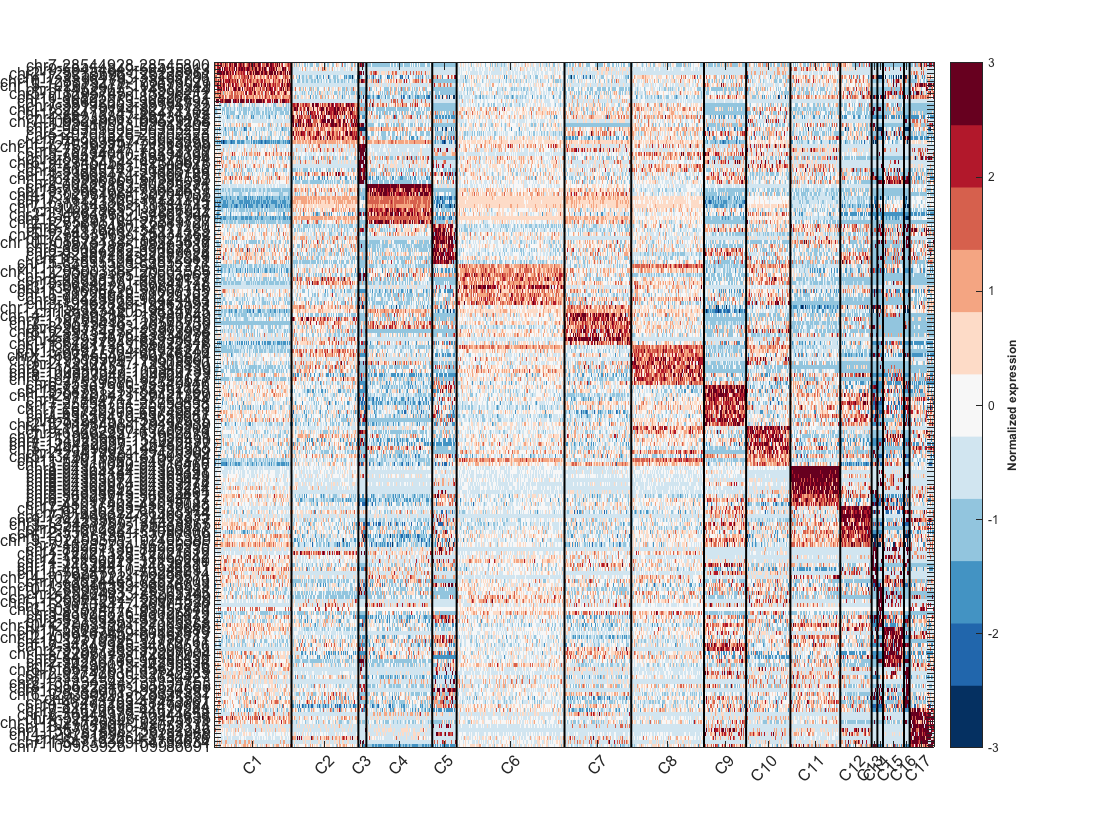

plot_heatmap_markers(scale_ATACa,clust,Top10loci);

Identify the detail differential accessible loci and plot the heatmap of scATAC-seq and aggregated data

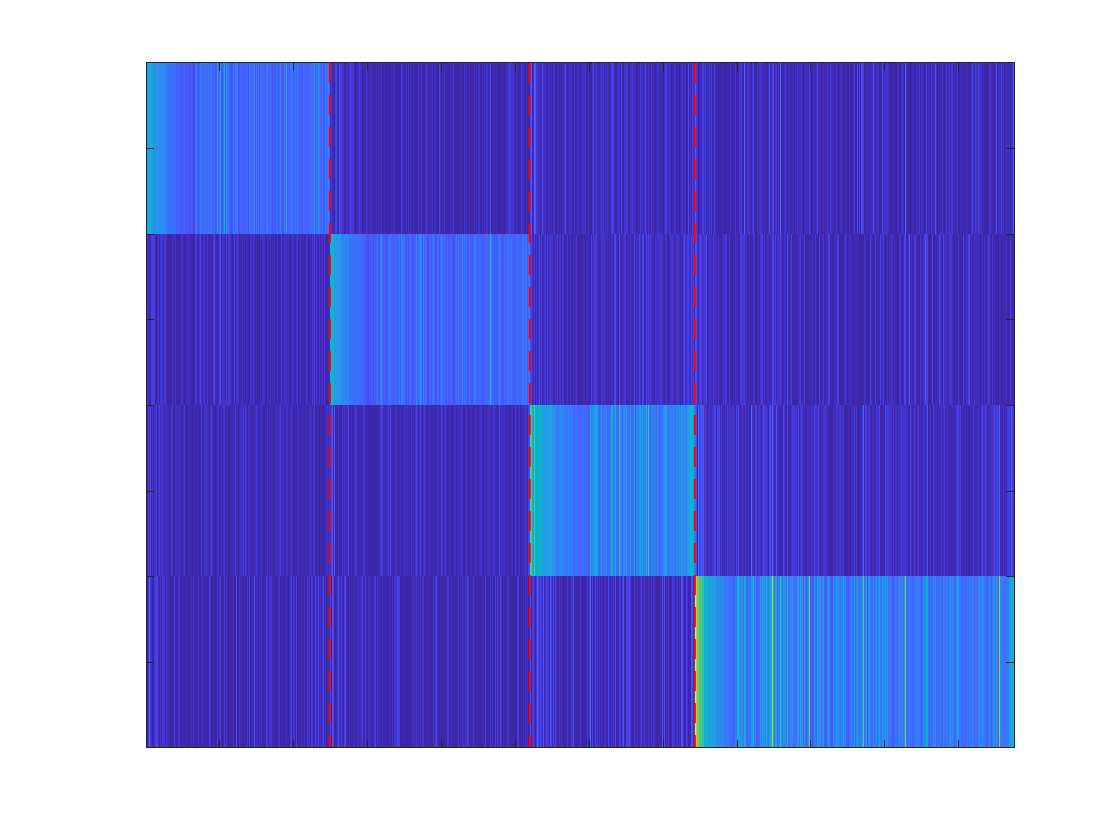

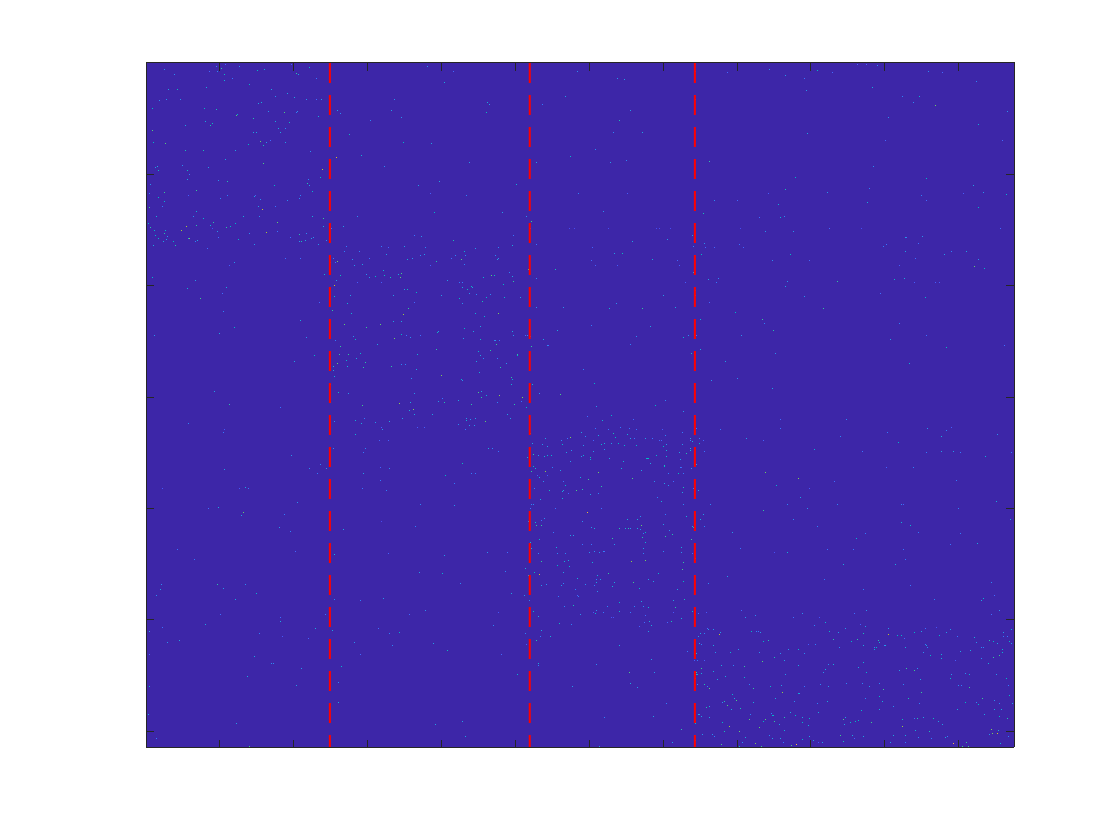

compare_index = [4,5,3,8];
warning ('off','all');
plot_accessibility_heatmap(X2,Loci,clust,compare_index,marker_loci);

#### 4 Visualize markers alongsize the cells in two-dimensions using VscAI

marker_loci = [];
[sample_coords,factor_coords] = getEmbeddings(RNA,ATACa,marker_genes,...
    marker_loci,best_one,system_used,alpha,lambda,gamma,s);

Loading required package: ggplot2
Loading required package: cowplot

Attaching package: ‘cowplot’

The following object is masked from ‘package:ggplot2’:

    ggsave

Loading required package: Matrix
Warning messages:
1: package ‘ggplot2’ was built under R version 3.5.2 
2: package ‘cowplot’ was built under R version 3.5.2 
3: package ‘Matrix’ was built under R version 3.5.2 

Attaching package: ‘swne’

The following object is masked from ‘package:Seurat’:

    ExtractField

Initial stress        : 0.30966
stress after  10 iters: 0.10895, magic = 0.461
stress after  20 iters: 0.10202, magic = 0.500
stress after  30 iters: 0.10188, magic = 0.500
stress after  40 iters: 0.10186, magic = 0.500


Visualize marker genes across all cells

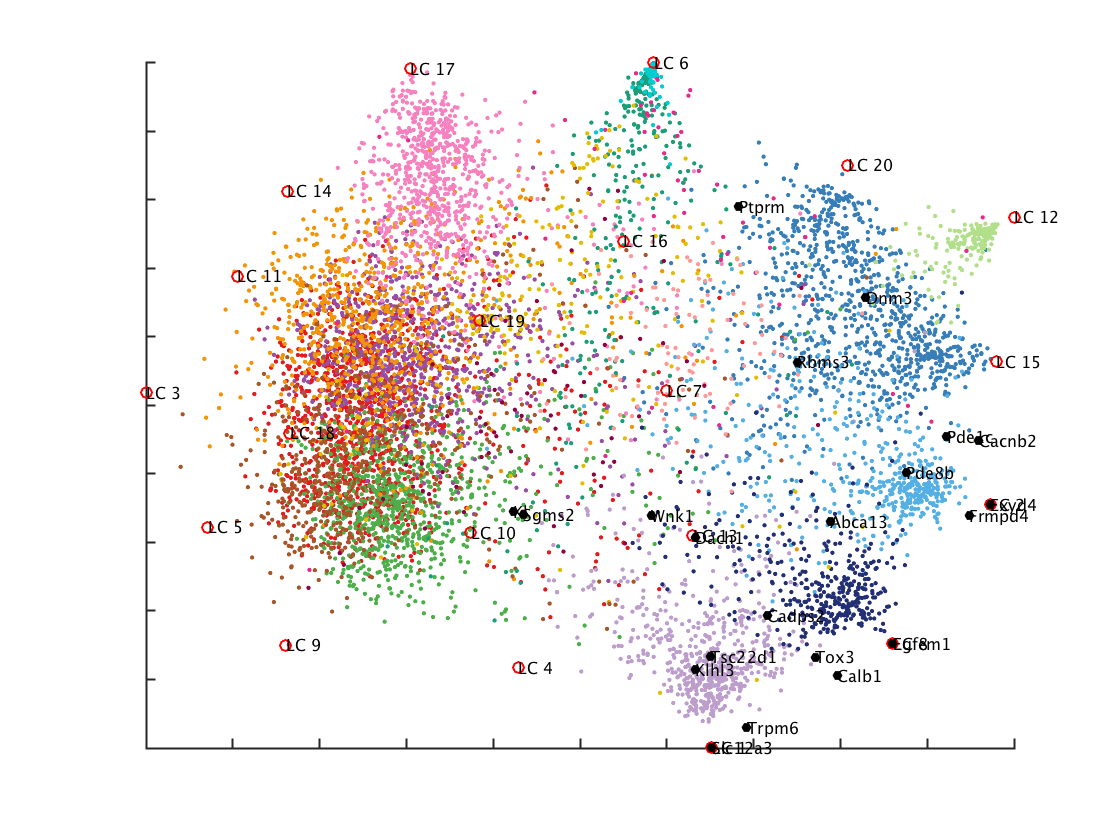

marker_genes_coords = readtable('./intermediateFiles/marker_coords_X1.txt',...
    'ReadRowNames',1);
term = [];
colors = generateColors(length(unique(clust)));
VscAIplot(sample_coords,factor_coords,marker_genes_coords,[],[],clust,term,...
    colors);